# 3.9. [Индукция](https://ru.wikipedia.org/wiki/%D0%9C%D0%B0%D0%B3%D0%BD%D0%B8%D1%82%D0%BD%D0%B0%D1%8F_%D0%B8%D0%BD%D0%B4%D1%83%D0%BA%D1%86%D0%B8%D1%8F) и индуктивность

#### Закон индукции (закон Фарадея-Генри)

clear
syms Phi_B(t) epsilon
epsilon==-diff(Phi_B,t)

$$ans(t) = \epsilon =-\frac{\partial }{\partial t}\Phi_{B}\left(t\right)$$

% epsilon = ЭДС индукции


$$\oint \mathit{\mathbf{E}}\;\mathbf{dr}=-\frac{\textrm{d}}{\textrm{d}t}\int \mathit{\mathbf{B}}\;\mathbf{dS}$$


syms E(r) B(S,t)
int(E(r),r)==-diff(int(B(S,t),S),t)

$$ans = \int \text{E}\left(r\right)\mathrm{d}r=-\int \frac{\partial }{\partial t}B\left(S,t\right)\mathrm{d}S$$

#### ЭДС индукции в соленоиде

syms N
epsilon==-N*diff(Phi_B,t)

$$ans(t) = \epsilon =-N\,\frac{\partial }{\partial t}\Phi_{B}\left(t\right)$$

#### Закон Ленца

Индукционный ток направлен так, что его собственное магнитное поле препятствует изменению потока магнитной индукции внешнего поля, которое вызывает этот ток.

#### Определение [индуктивности](https://ru.wikipedia.org/wiki/%D0%98%D0%BD%D0%B4%D1%83%D0%BA%D1%82%D0%B8%D0%B2%D0%BD%D0%BE%D1%81%D1%82%D1%8C) L

syms N Phi_B L I
N*Phi_B==L*I

$$ans = N\,\Phi_{B}=\text{I}\,L$$

#### Падение напряжения на катушке индуктивности

syms V_L L I(t)
V_L==L*diff(I)

$$ans(t) = V_{L}=L\,\frac{\partial }{\partial t}\text{I}\left(t\right)$$

#### Индуктивность длинного прямого или тороидального соленоида длины l

syms L mu0 n A l
L==mu0*N^2*A/l

$$ans = L=\frac{A\,N^{2}\,\mu_{0}}{l}$$

#### Индуктивность коаксиального кабеля

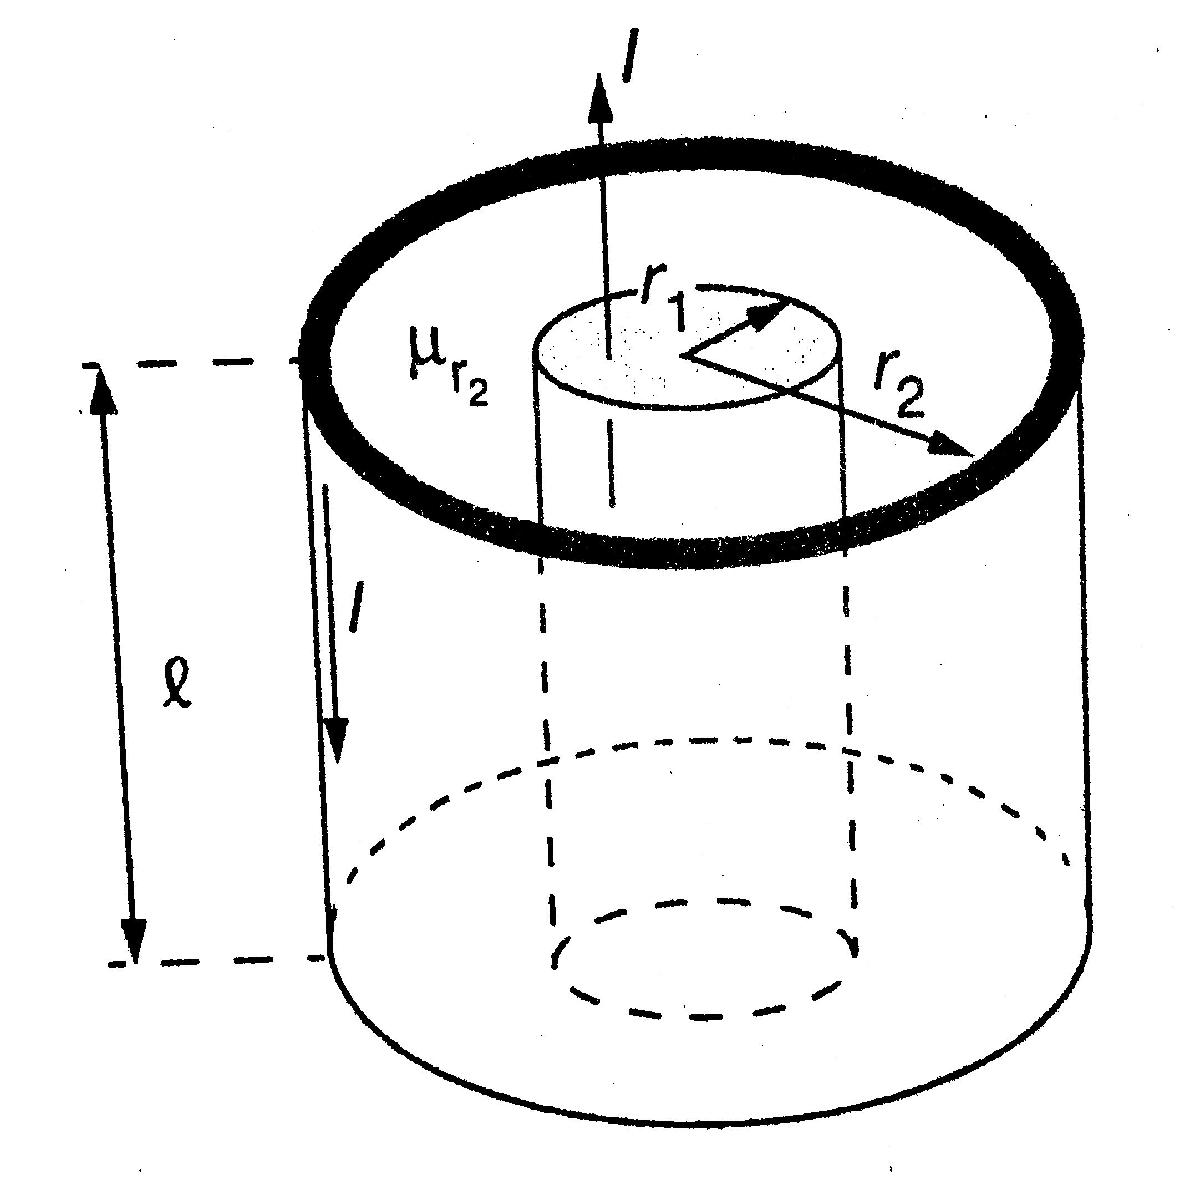

syms L mu2 mu1 mu0 r1 r2 l
L==mu2*mu0*l/(2*pi)*log(r2/r1)+mu1*mu0*l/(8*pi)

$$ans = L=\frac{l\,\mu_{0}\,\mu_{1}}{8\,\pi }+\frac{l\,\mu_{0}\,\mu_{2}\,\log\left(\frac{r_{2}}{r_{1}}\right)}{2\,\pi }$$

% mu1 = относительная магнитная проницаемость
% внутреннего проводника
% (Толщиной внешнего проводника пренебрегаем)

#### Эквивалентная индуктивность катушек индуктивности при последовательном и параллельном сединениях

syms L_s L_p L(n)
L_s==symsum(L(n),n)

$$ans = L_{s}=\sum_{n}L\left(n\right)$$

1/L_p==symsum(1/L(n),n)

$$ans = \frac{1}{L_{p}}=\sum_{n}\frac{1}{L\left(n\right)}$$

#### Возбуждение и обесточивание катушки индуктивности

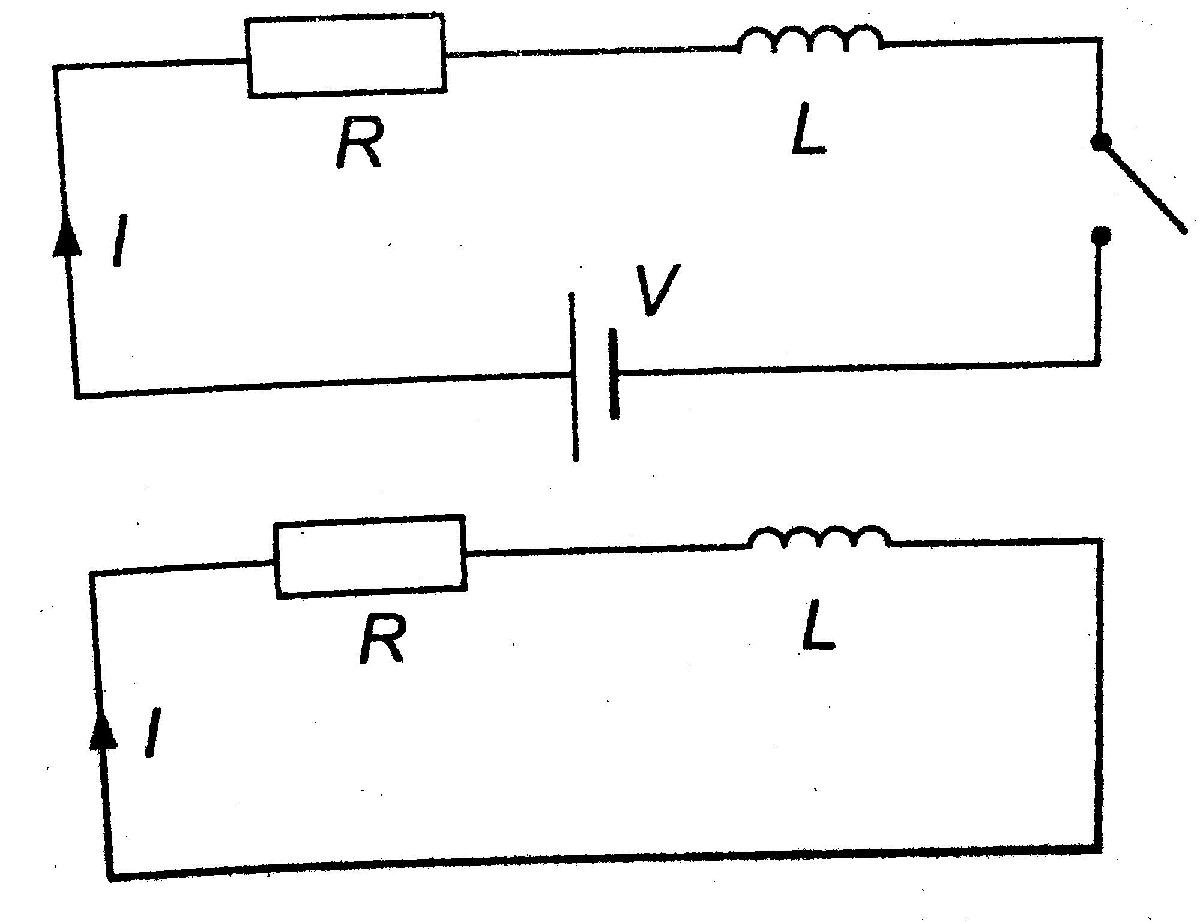

syms V R I L I(t)
V==R*I+L*diff(I,t)

$$ans(t) = V=L\,\frac{\partial }{\partial t}\text{I}\left(t\right)+R\,\text{I}\left(t\right)$$

syms I I0 R L t
I==I0*(1-exp(R/L*t))

$$ans = \text{I}=-I_{0}\,\left({\mathrm{e}}^{\frac{R\,t}{L}}-1\right)$$

I==I0*exp(-R/L*t)

$$ans = \text{I}=I_{0}\,{\mathrm{e}}^{-\frac{R\,t}{L}}$$

#### Энергия, накопленная в соленоидальном магнитном поле

syms W_L L I
W_L==1/2*L*I^2

$$ans = W_{L}=\frac{{\text{I}}^{2}\,L}{2}$$

#### Плотность энергии

syms w_m mu mu0 B
w_m==1/(2*mu*mu0)*B^2

$$ans = w_{m}=\frac{B^{2}}{2\,\mu \,\mu_{0}}$$

#### Определение взаимоиндуктивности M

syms N1 N2 Phi12 Phi21 M I1 I2
N2*Phi12==M*I1,...
N1*Phi21==M*I2

$$ans = N_{2}\,\Phi_{12}=I_{1}\,M$$

$$ans = N_{1}\,\Phi_{21}=I_{2}\,M$$

% Phi12 = поток, созданный катушкой 1, действующий на катушку 2
% (в большинстве случаев = Phi1)

#### Коэффициент связи

syms k M L1 L2
k==M/sqrt(L1*L2), abs(k)<1

$$ans = k=\frac{M}{\sqrt{L_{1}\,L_{2}}}$$

$$ans = \left|k\right|<1$$

*Пример.* Воздушный трансформатор

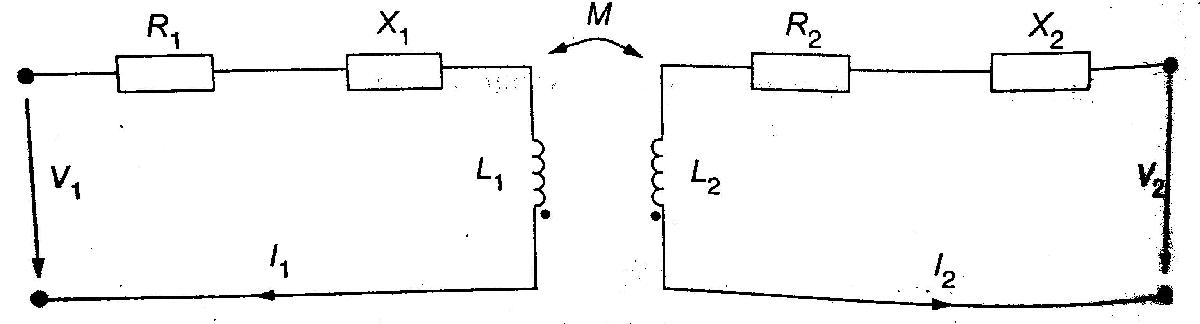

syms Z1 Z2 R1 R2 X1 X2 V1 V2 omega I1 I2 M
Z1==R1+1j*X1, V1==(Z1+1j*omega*L1)*I1+1j*omega*M*I2 

$$ans = Z_{1}=R_{1}+X_{1}\,\mathrm{i}$$

$$ans = V_{1}=I_{1}\,\left(Z_{1}+L_{1}\,\omega \,\mathrm{i}\right)+I_{2}\,M\,\omega \,\mathrm{i}$$

Z2==R2+1j*X2, V2==(Z2+1j*omega*L2)*I2+1j*omega*M*I1

$$ans = Z_{2}=R_{2}+X_{2}\,\mathrm{i}$$

$$ans = V_{2}=I_{2}\,\left(Z_{2}+L_{2}\,\omega \,\mathrm{i}\right)+I_{1}\,M\,\omega \,\mathrm{i}$$

#### Идеальный трансформатор

*Эквивалентная схема* 

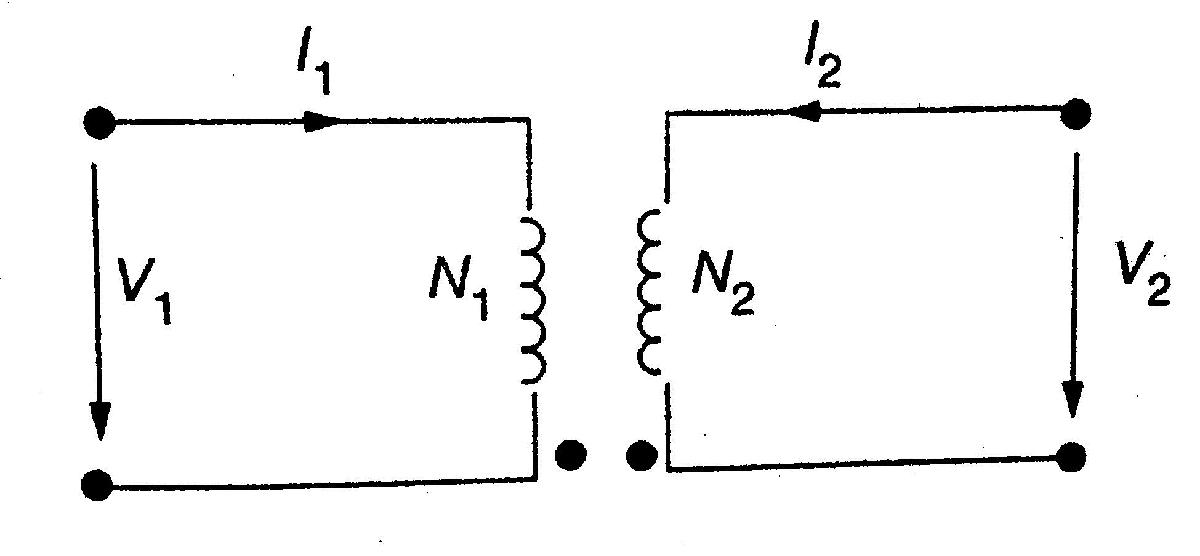

syms N1 N2 V1 V2 I1 I2
V2/V1==N2/N1

$$ans = \frac{V_{2}}{V_{1}}=\frac{N_{2}}{N_{1}}$$

I1*N1==-I2*N2

$$ans = I_{1}\,N_{1}=-I_{2}\,N_{2}$$

#### Реальный трансформатор

*Эквивалентная схема*

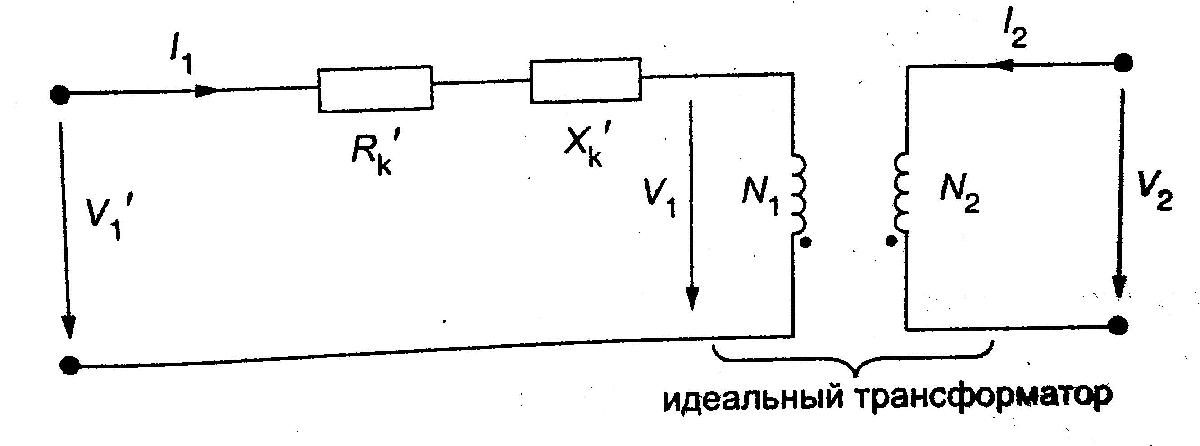 

syms R_k1 R1 R2 N X_k1
R_k1==R1+(N1/N2)^2*R2

$$ans = R_{\mathrm{k1}}=R_{1}+\frac{{N_{1}}^{2}\,R_{2}}{{N_{2}}^{2}}$$

X_k1==X1+(N1/N2)^2*X2

$$ans = X_{\mathrm{k1}}=X_{1}+\frac{{N_{1}}^{2}\,X_{2}}{{N_{2}}^{2}}$$

#### Коэффициента полезного действия трансформатора

syms eta P2 P0 P_b P1 V2 I2 phi2 x S_2M phi2 x
eta==P2/(P2+P0+P_b)

$$ans = \eta =\frac{P_{2}}{P_{0}+P_{2}+P_{b}}$$

P2==V2*I2*cos(phi2)==x*S_2M*cos(phi2)

$$ans = \left(P_{2}=I_{2}\,V_{2}\,\cos\left(\varphi_{2}\right)\right)=S_{\mathrm{2M}}\,x\,\cos\left(\varphi_{2}\right)$$

% x = коэффициент нагругзки, т.е. I2=x*I_2M
% I_2M = расчетная сила тока во вторичной обмотке
% S_2M=V_2M*I_2M = расчетная мощность во вторичной обмотке
% P0 = потери холостого режима (без нагрузки)
% P_b=x^2*P_bM = потери рабочего режима (с нагрузкой)
% P_bM = R_k1*I_1M^2 = максимальные потери в меди
% I_1M = расчетная сила тока в первичной обмотке.